#     P1. Dinámica Longitudinal del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 18 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta primera práctica definiremos las propiedades, los parámetros de diseño de nuestro monoplaza de competición FSDriverless y diseñaremos el primer modelo dinámica longitudinal. 

Para completar esta práctica se necesita conocer la ecuación fundamental de movimiento longitudinal de un vehículo desarrollada en el Bloque 2. 

Al terminar esta práctica deberás ser capaz de:

- Escribir y simular la ecuación de movimiento longitudinal de un vehículo.

- Cerrar un lazo sencillo de control de velocidad. 

- Reconocer la estructura de simulación que reutilizaremos y ampliaremos en las siguientes prácticas.

🚧 **Importante**: *este es el primer bloque de tu proyecto individual. El archivo que completes hoy se convertirá en la base longitudinal del simulador del sistema de control de tu monoplaza que utilizarás durante todo el curso. Guárdalo. *

#### Qué vas a implementar

A) La aceleración longitudinal (función `pasoLongitudinal`)

B) La ley de control PI saturada (función `controlLongitudinal`)

### Parametros del vehículo

💡 **Tip**: *Vamos a utilizar un *`struct`* (o estructura). En Matlab las estructuras son un tipo de datos que agrupa información relacionada mediante contenedores llamados campos. Cada campo puede almacenar cualquier tipo de dato (números, texto, vectores, u otras matrices).* 

p = struct();
p.m = 230; % masa del monoplaza sin conductor en kg 
p.g = 9.81; %Gravedad
p.rho = 1.225 % densidad del aire [kg/m^3]

p = struct with fields:
      m: 230
      g: 9.8100
    rho: 1.2250


p.Cd = 1.0;       % coeficiente de resistencia aerodinámica
p.Af = 1.1;        % área frontal [m^2]
p.fr = 0.022;    % coeficiente de resistencia a la rodadura
p.Fx_trac_max = 2500;   % fuerza motriz max [N]
p.Fx_fren_max = 5000; %fuerza de frenado max [N]
p.theta = 0; 

🧠 **Recordatorio**: la fuerza motriz máxima viene definida por el límite de adherencia del neumático y el límite de potencia/par del tren motriz. En el caso de la fuerza de frenado máxima, esta suele estar igualmente limitada por la adherencia pero con la ventaja del frenado de las cuatro ruedas (frente a un tracción trasera), lo que permite aprovechar el 100% de la masa del vehículo y la carga aerodinámica disponible.

### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal. Más adelante esta sección incluirá el modelo de nuestro vehículo al completo. 

Dada la posición del vehículo y la fuerza tractiva aplicada, deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

% Integración de la dinámica longitudinal
z0 = [0;0]; %vector de estados [x;v_x]

function z_next = pasoLongitudinal(z,u,p,dt)
    Fx = u;
    vx = z(2);

    %Resistencias 
    Ra = 0.5 * p.rho * p.Cd *p.Af * vx^2;% REsistencia aerodinamica
    Rr = p.fr* p.m*p.g *cos(p.theta) % rodadura
    Rg = p.m * p.g *sin(p.theta) % gravitatoria 

    %Aceleracion 
    ax = (Fx - Ra - sign(vx) * Rr - Rg )/p.m; 
    %Velocidad
    vx_next = max(vx + ax*dt,0) %velocidad en el siguiente instante de tiempo y pongo el max para si se para el coche q no siga metiendo error
    x_next = z(1) + vx*dt;
    z_next = z;
    z_next(1) = x_next;
    z_next(2) = vx_next; 
end 

### Controlador velocidad 

Vamos a definir aquí nuestro controlador de velocidad en base al siguiente diagrama:

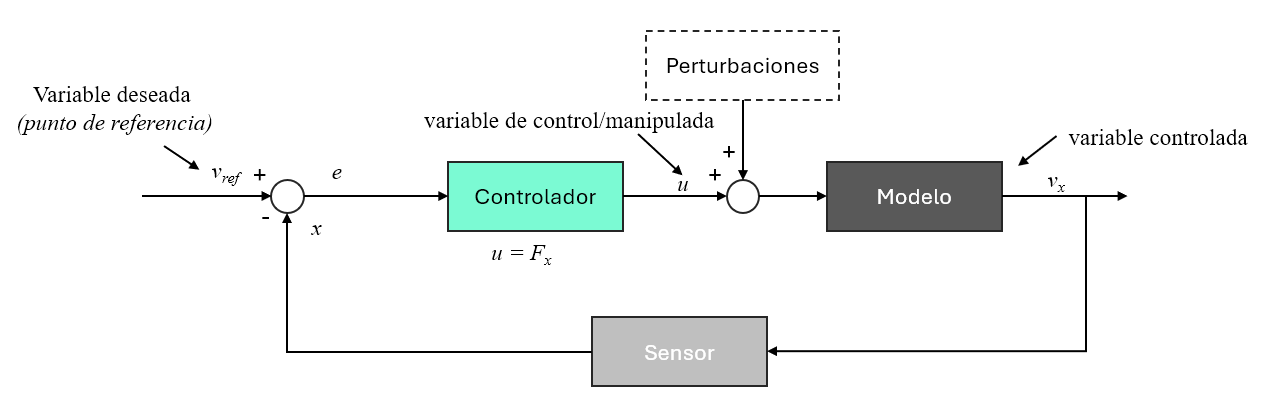

#### Recordatorio sobre controladores PI

Vamos a implementar un controlador PI de velocidad. Queremos que $v_x$ siga una referencia $v_{ref}$. El error, por tanto, vendrá definido por 


$$e = v_{ref} - v_x$$


y pedimos una fuerza de tracción proporcional a este error mas un termino integral que elimina el error en regimen permanente:


$$F_x = K_p \cdot e + K_i \int{e \cdot dt}$$


La fuerza real que se puede ejercer estará limitada por la adherencia y la capacidad de nuestro motor. $F_x
$ saturará entre máximo de frenado y el máximo de aceleración. 

**🧠Recordatorio**: *La saturación de un controlador ocurre cuando la señal de salida que calcula el controlador supera los límites físicos, eléctricos o de software del actuador que debe ejecutar la orden.*

💡*¿Por qué fuerza de tracción como variable de control? *Esta es una decisión que facilita la integración con la ecuación que gobierna el movimiento longitudinal. Es una manera de abstraer todo el tren de potencia (real) colapsándolo en una sola variable. En la realidad necesitaríamos modelar todo el tren de potencia (pedal del acelerador → par motor → fuerza tractiva) utilizando los mapas proprios del motor (no lineales para motores de combustion interna). 

% Controlador PI de velocidad
ctrl.v_cru = 25; %velocidad de crucero objetivo [m/s] posible optimización hacer dinámico la parte de la velocdad de crucero
ctrl.x_fren = 78; % Distancia a la que se ordena frenar [m]
ctrl.Kp = 800; %ganancia proporcional 
ctrl.Ki = 200;% Ganancia integral 

function [Fx , e_int] = controlLongitudinal(v_ref,vx,e_int,dt, ctrl, p) 
    e = v_ref - vx; 
    %integral del error
    e_int = e_int + e*dt;
    Fx = ctrl.Kp*e + ctrl.Ki*e_int; %CONTROLADOR PI

    % Limites de saturacion de mi controlador 
    Fx = min(max(Fx, -p.Fx_fren_max), p.Fx_trac_max);
end

### Geometría del circuito de pruebas

Vamos a simular una aceleración máxima durante 75 m seguida de una frenada en caja que deberá completarse en menos de 25 m (límite máximo de frenada a los 100 m). 

p.x_meta = 75;     % línea de cronometraje [m]
p.x_box  = 100;    % final de la caja de frenada [m]

%% SIMULADOR DE PRUEBA ACELERACIÓN Y FRENADA [NO MODIFICAR]
function [hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax)
    N = round(Tmax/dt);
    z = z0;
    hist.t  = zeros(1,N); hist.x  = zeros(1,N); hist.vx = zeros(1,N);
    hist.Fx = zeros(1,N); hist.vr = zeros(1,N);
    e_int = 0;  cruzada = false;  t_evento = NaN;  k_fin = N;
    for k = 1:N
        t = (k-1)*dt;
        if z(1) < ctrl.x_fren,  v_ref = ctrl.v_cru;  else,  v_ref = 0;  end
        [Fx, e_int] = controlLongitudinal(v_ref, z(2), e_int, dt, ctrl, p);
        z = pasoLongitudinal(z, Fx, p, dt);   % mando u = [Fx; delta]; delta = 0 en L1
        hist.t(k)=t; hist.x(k)=z(1); hist.vx(k)=z(2); hist.Fx(k)=Fx; hist.vr(k)=v_ref;
        if ~cruzada && z(1) >= p.x_meta,  cruzada = true;  t_evento = t;  end
        if cruzada && z(2) <= 0.05,  k_fin = k;  break;  end
    end
    f = 1:k_fin;
    hist.t=hist.t(f); hist.X=hist.x(f); hist.vx=hist.vx(f);
    hist.Fx=hist.Fx(f); hist.vr=hist.vr(f);
end

### Simulación

dt   = 0.005;
Tmax = 20; 

[hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax);

Rr = 49.6386

Rg = 0

vx_next = 0.0543

Rr = 49.6386

Rg = 0

vx_next = 0.1076

Rr = 49.6386

Rg = 0

vx_next = 0.1609

Rr = 49.6386

Rg = 0

vx_next = 0.2142

Rr = 49.6386

Rg = 0

vx_next = 0.2674

Rr = 49.6386

Rg = 0

vx_next = 0.3207

Rr = 49.6386

Rg = 0

vx_next = 0.3740

Rr = 49.6386

Rg = 0

vx_next = 0.4272

Rr = 49.6386

Rg = 0

vx_next = 0.4805

Rr = 49.6386

Rg = 0

vx_next = 0.5338

Rr = 49.6386

Rg = 0

vx_next = 0.5870

Rr = 49.6386

Rg = 0

vx_next = 0.6403

Rr = 49.6386

Rg = 0

vx_next = 0.6935

Rr = 49.6386

Rg = 0

vx_next = 0.7468

Rr = 49.6386

Rg = 0

vx_next = 0.8001

Rr = 49.6386

Rg = 0

vx_next = 0.8533

Rr = 49.6386

Rg = 0

vx_next = 0.9066

Rr = 49.6386

Rg = 0

vx_next = 0.9598

Rr = 49.6386

Rg = 0

vx_next = 1.0131

Rr = 49.6386

Rg = 0

vx_next = 1.0664

Rr = 49.6386

Rg = 0

vx_next = 1.1196

Rr = 49.6386

Rg = 0

vx_next = 1.1729

Rr = 49.6386

Rg = 0

vx_next = 1.2261

Rr = 49.6386

Rg = 0

vx_next = 1.2793

Rr = 49.6386

Rg = 0

vx_next = 1.3326

Rr = 49.6386

Rg = 0

vx_next = 1.3858

Rr = 49.6386

Rg = 0

vx_next = 1.4391

Rr = 49.6386

Rg = 0

vx_next = 1.4923

Rr = 49.6386

Rg = 0

vx_next = 1.5456

Rr = 49.6386

Rg = 0

vx_next = 1.5988

Rr = 49.6386

Rg = 0

vx_next = 1.6520

Rr = 49.6386

Rg = 0

vx_next = 1.7052

Rr = 49.6386

Rg = 0

vx_next = 1.7585

Rr = 49.6386

Rg = 0

vx_next = 1.8117

Rr = 49.6386

Rg = 0

vx_next = 1.8649

Rr = 49.6386

Rg = 0

vx_next = 1.9181

Rr = 49.6386

Rg = 0

vx_next = 1.9713

Rr = 49.6386

Rg = 0

vx_next = 2.0246

Rr = 49.6386

Rg = 0

vx_next = 2.0778

Rr = 49.6386

Rg = 0

vx_next = 2.1310

Rr = 49.6386

Rg = 0

vx_next = 2.1842

Rr = 49.6386

Rg = 0

vx_next = 2.2374

Rr = 49.6386

Rg = 0

vx_next = 2.2906

Rr = 49.6386

Rg = 0

vx_next = 2.3438

Rr = 49.6386

Rg = 0

vx_next = 2.3970

Rr = 49.6386

Rg = 0

vx_next = 2.4501

Rr = 49.6386

Rg = 0

vx_next = 2.5033

Rr = 49.6386

Rg = 0

vx_next = 2.5565

Rr = 49.6386

Rg = 0

vx_next = 2.6097

Rr = 49.6386

Rg = 0

vx_next = 2.6628

Rr = 49.6386

Rg = 0

vx_next = 2.7160

Rr = 49.6386

Rg = 0

vx_next = 2.7692

Rr = 49.6386

Rg = 0

vx_next = 2.8223

Rr = 49.6386

Rg = 0

vx_next = 2.8755

Rr = 49.6386

Rg = 0

vx_next = 2.9286

Rr = 49.6386

Rg = 0

vx_next = 2.9818

Rr = 49.6386

Rg = 0

vx_next = 3.0349

Rr = 49.6386

Rg = 0

vx_next = 3.0880

Rr = 49.6386

Rg = 0

vx_next = 3.1412

Rr = 49.6386

Rg = 0

vx_next = 3.1943

Rr = 49.6386

Rg = 0

vx_next = 3.2474

Rr = 49.6386

Rg = 0

vx_next = 3.3005

Rr = 49.6386

Rg = 0

vx_next = 3.3536

Rr = 49.6386

Rg = 0

vx_next = 3.4067

Rr = 49.6386

Rg = 0

vx_next = 3.4598

Rr = 49.6386

Rg = 0

vx_next = 3.5129

Rr = 49.6386

Rg = 0

vx_next = 3.5660

Rr = 49.6386

Rg = 0

vx_next = 3.6191

Rr = 49.6386

Rg = 0

vx_next = 3.6722

Rr = 49.6386

Rg = 0

vx_next = 3.7252

Rr = 49.6386

Rg = 0

vx_next = 3.7783

Rr = 49.6386

Rg = 0

vx_next = 3.8314

Rr = 49.6386

Rg = 0

vx_next = 3.8844

Rr = 49.6386

Rg = 0

vx_next = 3.9375

Rr = 49.6386

Rg = 0

vx_next = 3.9905

Rr = 49.6386

Rg = 0

vx_next = 4.0435

Rr = 49.6386

Rg = 0

vx_next = 4.0966

Rr = 49.6386

Rg = 0

vx_next = 4.1496

Rr = 49.6386

Rg = 0

vx_next = 4.2026

Rr = 49.6386

Rg = 0

vx_next = 4.2556

Rr = 49.6386

Rg = 0

vx_next = 4.3086

Rr = 49.6386

Rg = 0

vx_next = 4.3616

Rr = 49.6386

Rg = 0

vx_next = 4.4146

Rr = 49.6386

Rg = 0

vx_next = 4.4676

Rr = 49.6386

Rg = 0

vx_next = 4.5206

Rr = 49.6386

Rg = 0

vx_next = 4.5735

Rr = 49.6386

Rg = 0

vx_next = 4.6265

Rr = 49.6386

Rg = 0

vx_next = 4.6795

Rr = 49.6386

Rg = 0

vx_next = 4.7324

Rr = 49.6386

Rg = 0

vx_next = 4.7854

Rr = 49.6386

Rg = 0

vx_next = 4.8383

Rr = 49.6386

Rg = 0

vx_next = 4.8912

Rr = 49.6386

Rg = 0

vx_next = 4.9441

Rr = 49.6386

Rg = 0

vx_next = 4.9970

Rr = 49.6386

Rg = 0

vx_next = 5.0499

Rr = 49.6386

Rg = 0

vx_next = 5.1028

Rr = 49.6386

Rg = 0

vx_next = 5.1557

Rr = 49.6386

Rg = 0

vx_next = 5.2086

Rr = 49.6386

Rg = 0

vx_next = 5.2615

Rr = 49.6386

Rg = 0

vx_next = 5.3143

Rr = 49.6386

Rg = 0

vx_next = 5.3672

Rr = 49.6386

Rg = 0

vx_next = 5.4200

Rr = 49.6386

Rg = 0

vx_next = 5.4729

Rr = 49.6386

Rg = 0

vx_next = 5.5257

Rr = 49.6386

Rg = 0

vx_next = 5.5785

Rr = 49.6386

Rg = 0

vx_next = 5.6313

Rr = 49.6386

Rg = 0

vx_next = 5.6841

Rr = 49.6386

Rg = 0

vx_next = 5.7369

Rr = 49.6386

Rg = 0

vx_next = 5.7897

Rr = 49.6386

Rg = 0

vx_next = 5.8425

Rr = 49.6386

Rg = 0

vx_next = 5.8953

Rr = 49.6386

Rg = 0

vx_next = 5.9480

Rr = 49.6386

Rg = 0

vx_next = 6.0008

Rr = 49.6386

Rg = 0

vx_next = 6.0535

Rr = 49.6386

Rg = 0

vx_next = 6.1063

Rr = 49.6386

Rg = 0

vx_next = 6.1590

Rr = 49.6386

Rg = 0

vx_next = 6.2117

Rr = 49.6386

Rg = 0

vx_next = 6.2644

Rr = 49.6386

Rg = 0

vx_next = 6.3171

Rr = 49.6386

Rg = 0

vx_next = 6.3698

Rr = 49.6386

Rg = 0

vx_next = 6.4225

Rr = 49.6386

Rg = 0

vx_next = 6.4751

Rr = 49.6386

Rg = 0

vx_next = 6.5278

Rr = 49.6386

Rg = 0

vx_next = 6.5804

Rr = 49.6386

Rg = 0

vx_next = 6.6330

Rr = 49.6386

Rg = 0

vx_next = 6.6857

Rr = 49.6386

Rg = 0

vx_next = 6.7383

Rr = 49.6386

Rg = 0

vx_next = 6.7909

Rr = 49.6386

Rg = 0

vx_next = 6.8435

Rr = 49.6386

Rg = 0

vx_next = 6.8961

Rr = 49.6386

Rg = 0

vx_next = 6.9486

Rr = 49.6386

Rg = 0

vx_next = 7.0012

Rr = 49.6386

Rg = 0

vx_next = 7.0538

Rr = 49.6386

Rg = 0

vx_next = 7.1063

Rr = 49.6386

Rg = 0

vx_next = 7.1588

Rr = 49.6386

Rg = 0

vx_next = 7.2113

Rr = 49.6386

Rg = 0

vx_next = 7.2638

Rr = 49.6386

Rg = 0

vx_next = 7.3163

Rr = 49.6386

Rg = 0

vx_next = 7.3688

Rr = 49.6386

Rg = 0

vx_next = 7.4213

Rr = 49.6386

Rg = 0

vx_next = 7.4738

Rr = 49.6386

Rg = 0

vx_next = 7.5262

Rr = 49.6386

Rg = 0

vx_next = 7.5787

Rr = 49.6386

Rg = 0

vx_next = 7.6311

Rr = 49.6386

Rg = 0

vx_next = 7.6835

Rr = 49.6386

Rg = 0

vx_next = 7.7359

Rr = 49.6386

Rg = 0

vx_next = 7.7883

Rr = 49.6386

Rg = 0

vx_next = 7.8407

Rr = 49.6386

Rg = 0

vx_next = 7.8930

Rr = 49.6386

Rg = 0

vx_next = 7.9454

Rr = 49.6386

Rg = 0

vx_next = 7.9977

Rr = 49.6386

Rg = 0

vx_next = 8.0501

Rr = 49.6386

Rg = 0

vx_next = 8.1024

Rr = 49.6386

Rg = 0

vx_next = 8.1547

Rr = 49.6386

Rg = 0

vx_next = 8.2070

Rr = 49.6386

Rg = 0

vx_next = 8.2593

Rr = 49.6386

Rg = 0

vx_next = 8.3115

Rr = 49.6386

Rg = 0

vx_next = 8.3638

Rr = 49.6386

Rg = 0

vx_next = 8.4160

Rr = 49.6386

Rg = 0

vx_next = 8.4683

Rr = 49.6386

Rg = 0

vx_next = 8.5205

Rr = 49.6386

Rg = 0

vx_next = 8.5727

Rr = 49.6386

Rg = 0

vx_next = 8.6249

Rr = 49.6386

Rg = 0

vx_next = 8.6771

Rr = 49.6386

Rg = 0

vx_next = 8.7292

Rr = 49.6386

Rg = 0

vx_next = 8.7814

Rr = 49.6386

Rg = 0

vx_next = 8.8335

Rr = 49.6386

Rg = 0

vx_next = 8.8857

Rr = 49.6386

Rg = 0

vx_next = 8.9378

Rr = 49.6386

Rg = 0

vx_next = 8.9899

Rr = 49.6386

Rg = 0

vx_next = 9.0420

Rr = 49.6386

Rg = 0

vx_next = 9.0940

Rr = 49.6386

Rg = 0

vx_next = 9.1461

Rr = 49.6386

Rg = 0

vx_next = 9.1981

Rr = 49.6386

Rg = 0

vx_next = 9.2502

Rr = 49.6386

Rg = 0

vx_next = 9.3022

Rr = 49.6386

Rg = 0

vx_next = 9.3542

Rr = 49.6386

Rg = 0

vx_next = 9.4062

Rr = 49.6386

Rg = 0

vx_next = 9.4581

Rr = 49.6386

Rg = 0

vx_next = 9.5101

Rr = 49.6386

Rg = 0

vx_next = 9.5620

Rr = 49.6386

Rg = 0

vx_next = 9.6140

Rr = 49.6386

Rg = 0

vx_next = 9.6659

Rr = 49.6386

Rg = 0

vx_next = 9.7178

Rr = 49.6386

Rg = 0

vx_next = 9.7697

Rr = 49.6386

Rg = 0

vx_next = 9.8215

Rr = 49.6386

Rg = 0

vx_next = 9.8734

Rr = 49.6386

Rg = 0

vx_next = 9.9252

Rr = 49.6386

Rg = 0

vx_next = 9.9771

Rr = 49.6386

Rg = 0

vx_next = 10.0289

Rr = 49.6386

Rg = 0

vx_next = 10.0807

Rr = 49.6386

Rg = 0

vx_next = 10.1324

Rr = 49.6386

Rg = 0

vx_next = 10.1842

Rr = 49.6386

Rg = 0

vx_next = 10.2360

Rr = 49.6386

Rg = 0

vx_next = 10.2877

Rr = 49.6386

Rg = 0

vx_next = 10.3394

Rr = 49.6386

Rg = 0

vx_next = 10.3911

Rr = 49.6386

Rg = 0

vx_next = 10.4428

Rr = 49.6386

Rg = 0

vx_next = 10.4945

Rr = 49.6386

Rg = 0

vx_next = 10.5461

Rr = 49.6386

Rg = 0

vx_next = 10.5978

Rr = 49.6386

Rg = 0

vx_next = 10.6494

Rr = 49.6386

Rg = 0

vx_next = 10.7010

Rr = 49.6386

Rg = 0

vx_next = 10.7526

Rr = 49.6386

Rg = 0

vx_next = 10.8042

Rr = 49.6386

Rg = 0

vx_next = 10.8557

Rr = 49.6386

Rg = 0

vx_next = 10.9073

Rr = 49.6386

Rg = 0

vx_next = 10.9588

Rr = 49.6386

Rg = 0

vx_next = 11.0103

Rr = 49.6386

Rg = 0

vx_next = 11.0618

Rr = 49.6386

Rg = 0

vx_next = 11.1133

Rr = 49.6386

Rg = 0

vx_next = 11.1647

Rr = 49.6386

Rg = 0

vx_next = 11.2162

Rr = 49.6386

Rg = 0

vx_next = 11.2676

Rr = 49.6386

Rg = 0

vx_next = 11.3190

Rr = 49.6386

Rg = 0

vx_next = 11.3704

Rr = 49.6386

Rg = 0

vx_next = 11.4218

Rr = 49.6386

Rg = 0

vx_next = 11.4731

Rr = 49.6386

Rg = 0

vx_next = 11.5245

Rr = 49.6386

Rg = 0

vx_next = 11.5758

Rr = 49.6386

Rg = 0

vx_next = 11.6271

Rr = 49.6386

Rg = 0

vx_next = 11.6784

Rr = 49.6386

Rg = 0

vx_next = 11.7297

Rr = 49.6386

Rg = 0

vx_next = 11.7809

Rr = 49.6386

Rg = 0

vx_next = 11.8322

Rr = 49.6386

Rg = 0

vx_next = 11.8834

Rr = 49.6386

Rg = 0

vx_next = 11.9346

Rr = 49.6386

Rg = 0

vx_next = 11.9858

Rr = 49.6386

Rg = 0

vx_next = 12.0369

Rr = 49.6386

Rg = 0

vx_next = 12.0881

Rr = 49.6386

Rg = 0

vx_next = 12.1392

Rr = 49.6386

Rg = 0

vx_next = 12.1903

Rr = 49.6386

Rg = 0

vx_next = 12.2414

Rr = 49.6386

Rg = 0

vx_next = 12.2925

Rr = 49.6386

Rg = 0

vx_next = 12.3435

Rr = 49.6386

Rg = 0

vx_next = 12.3946

Rr = 49.6386

Rg = 0

vx_next = 12.4456

Rr = 49.6386

Rg = 0

vx_next = 12.4966

Rr = 49.6386

Rg = 0

vx_next = 12.5476

Rr = 49.6386

Rg = 0

vx_next = 12.5985

Rr = 49.6386

Rg = 0

vx_next = 12.6495

Rr = 49.6386

Rg = 0

vx_next = 12.7004

Rr = 49.6386

Rg = 0

vx_next = 12.7513

Rr = 49.6386

Rg = 0

vx_next = 12.8022

Rr = 49.6386

Rg = 0

vx_next = 12.8531

Rr = 49.6386

Rg = 0

vx_next = 12.9039

Rr = 49.6386

Rg = 0

vx_next = 12.9547

Rr = 49.6386

Rg = 0

vx_next = 13.0055

Rr = 49.6386

Rg = 0

vx_next = 13.0563

Rr = 49.6386

Rg = 0

vx_next = 13.1071

Rr = 49.6386

Rg = 0

vx_next = 13.1579

Rr = 49.6386

Rg = 0

vx_next = 13.2086

Rr = 49.6386

Rg = 0

vx_next = 13.2593

Rr = 49.6386

Rg = 0

vx_next = 13.3100

Rr = 49.6386

Rg = 0

vx_next = 13.3607

Rr = 49.6386

Rg = 0

vx_next = 13.4113

Rr = 49.6386

Rg = 0

vx_next = 13.4620

Rr = 49.6386

Rg = 0

vx_next = 13.5126

Rr = 49.6386

Rg = 0

vx_next = 13.5632

Rr = 49.6386

Rg = 0

vx_next = 13.6138

Rr = 49.6386

Rg = 0

vx_next = 13.6643

Rr = 49.6386

Rg = 0

vx_next = 13.7148

Rr = 49.6386

Rg = 0

vx_next = 13.7654

Rr = 49.6386

Rg = 0

vx_next = 13.8158

Rr = 49.6386

Rg = 0

vx_next = 13.8663

Rr = 49.6386

Rg = 0

vx_next = 13.9168

Rr = 49.6386

Rg = 0

vx_next = 13.9672

Rr = 49.6386

Rg = 0

vx_next = 14.0176

Rr = 49.6386

Rg = 0

vx_next = 14.0680

Rr = 49.6386

Rg = 0

vx_next = 14.1184

Rr = 49.6386

Rg = 0

vx_next = 14.1687

Rr = 49.6386

Rg = 0

vx_next = 14.2191

Rr = 49.6386

Rg = 0

vx_next = 14.2694

Rr = 49.6386

Rg = 0

vx_next = 14.3196

Rr = 49.6386

Rg = 0

vx_next = 14.3699

Rr = 49.6386

Rg = 0

vx_next = 14.4202

Rr = 49.6386

Rg = 0

vx_next = 14.4704

Rr = 49.6386

Rg = 0

vx_next = 14.5206

Rr = 49.6386

Rg = 0

vx_next = 14.5708

Rr = 49.6386

Rg = 0

vx_next = 14.6209

Rr = 49.6386

Rg = 0

vx_next = 14.6711

Rr = 49.6386

Rg = 0

vx_next = 14.7212

Rr = 49.6386

Rg = 0

vx_next = 14.7713

Rr = 49.6386

Rg = 0

vx_next = 14.8213

Rr = 49.6386

Rg = 0

vx_next = 14.8714

Rr = 49.6386

Rg = 0

vx_next = 14.9214

Rr = 49.6386

Rg = 0

vx_next = 14.9714

Rr = 49.6386

Rg = 0

vx_next = 15.0214

Rr = 49.6386

Rg = 0

vx_next = 15.0714

Rr = 49.6386

Rg = 0

vx_next = 15.1213

Rr = 49.6386

Rg = 0

vx_next = 15.1712

Rr = 49.6386

Rg = 0

vx_next = 15.2211

Rr = 49.6386

Rg = 0

vx_next = 15.2710

Rr = 49.6386

Rg = 0

vx_next = 15.3209

Rr = 49.6386

Rg = 0

vx_next = 15.3707

Rr = 49.6386

Rg = 0

vx_next = 15.4205

Rr = 49.6386

Rg = 0

vx_next = 15.4703

Rr = 49.6386

Rg = 0

vx_next = 15.5201

Rr = 49.6386

Rg = 0

vx_next = 15.5698

Rr = 49.6386

Rg = 0

vx_next = 15.6195

Rr = 49.6386

Rg = 0

vx_next = 15.6692

Rr = 49.6386

Rg = 0

vx_next = 15.7189

Rr = 49.6386

Rg = 0

vx_next = 15.7685

Rr = 49.6386

Rg = 0

vx_next = 15.8182

Rr = 49.6386

Rg = 0

vx_next = 15.8678

Rr = 49.6386

Rg = 0

vx_next = 15.9173

Rr = 49.6386

Rg = 0

vx_next = 15.9669

Rr = 49.6386

Rg = 0

vx_next = 16.0164

Rr = 49.6386

Rg = 0

vx_next = 16.0659

Rr = 49.6386

Rg = 0

vx_next = 16.1154

Rr = 49.6386

Rg = 0

vx_next = 16.1649

Rr = 49.6386

Rg = 0

vx_next = 16.2143

Rr = 49.6386

Rg = 0

vx_next = 16.2638

Rr = 49.6386

Rg = 0

vx_next = 16.3132

Rr = 49.6386

Rg = 0

vx_next = 16.3625

Rr = 49.6386

Rg = 0

vx_next = 16.4119

Rr = 49.6386

Rg = 0

vx_next = 16.4612

Rr = 49.6386

Rg = 0

vx_next = 16.5105

Rr = 49.6386

Rg = 0

vx_next = 16.5598

Rr = 49.6386

Rg = 0

vx_next = 16.6090

Rr = 49.6386

Rg = 0

vx_next = 16.6583

Rr = 49.6386

Rg = 0

vx_next = 16.7075

Rr = 49.6386

Rg = 0

vx_next = 16.7566

Rr = 49.6386

Rg = 0

vx_next = 16.8058

Rr = 49.6386

Rg = 0

vx_next = 16.8549

Rr = 49.6386

Rg = 0

vx_next = 16.9040

Rr = 49.6386

Rg = 0

vx_next = 16.9531

Rr = 49.6386

Rg = 0

vx_next = 17.0022

Rr = 49.6386

Rg = 0

vx_next = 17.0512

Rr = 49.6386

Rg = 0

vx_next = 17.1002

Rr = 49.6386

Rg = 0

vx_next = 17.1492

Rr = 49.6386

Rg = 0

vx_next = 17.1982

Rr = 49.6386

Rg = 0

vx_next = 17.2471

Rr = 49.6386

Rg = 0

vx_next = 17.2960

Rr = 49.6386

Rg = 0

vx_next = 17.3449

Rr = 49.6386

Rg = 0

vx_next = 17.3938

Rr = 49.6386

Rg = 0

vx_next = 17.4426

Rr = 49.6386

Rg = 0

vx_next = 17.4914

Rr = 49.6386

Rg = 0

vx_next = 17.5402

Rr = 49.6386

Rg = 0

vx_next = 17.5890

Rr = 49.6386

Rg = 0

vx_next = 17.6377

Rr = 49.6386

Rg = 0

vx_next = 17.6864

Rr = 49.6386

Rg = 0

vx_next = 17.7351

Rr = 49.6386

Rg = 0

vx_next = 17.7838

Rr = 49.6386

Rg = 0

vx_next = 17.8324

Rr = 49.6386

Rg = 0

vx_next = 17.8810

Rr = 49.6386

Rg = 0

vx_next = 17.9296

Rr = 49.6386

Rg = 0

vx_next = 17.9782

Rr = 49.6386

Rg = 0

vx_next = 18.0267

Rr = 49.6386

Rg = 0

vx_next = 18.0752

Rr = 49.6386

Rg = 0

vx_next = 18.1237

Rr = 49.6386

Rg = 0

vx_next = 18.1721

Rr = 49.6386

Rg = 0

vx_next = 18.2206

Rr = 49.6386

Rg = 0

vx_next = 18.2690

Rr = 49.6386

Rg = 0

vx_next = 18.3174

Rr = 49.6386

Rg = 0

vx_next = 18.3657

Rr = 49.6386

Rg = 0

vx_next = 18.4140

Rr = 49.6386

Rg = 0

vx_next = 18.4623

Rr = 49.6386

Rg = 0

vx_next = 18.5106

Rr = 49.6386

Rg = 0

vx_next = 18.5589

Rr = 49.6386

Rg = 0

vx_next = 18.6071

Rr = 49.6386

Rg = 0

vx_next = 18.6553

Rr = 49.6386

Rg = 0

vx_next = 18.7035

Rr = 49.6386

Rg = 0

vx_next = 18.7516

Rr = 49.6386

Rg = 0

vx_next = 18.7997

Rr = 49.6386

Rg = 0

vx_next = 18.8478

Rr = 49.6386

Rg = 0

vx_next = 18.8959

Rr = 49.6386

Rg = 0

vx_next = 18.9439

Rr = 49.6386

Rg = 0

vx_next = 18.9919

Rr = 49.6386

Rg = 0

vx_next = 19.0399

Rr = 49.6386

Rg = 0

vx_next = 19.0879

Rr = 49.6386

Rg = 0

vx_next = 19.1358

Rr = 49.6386

Rg = 0

vx_next = 19.1837

Rr = 49.6386

Rg = 0

vx_next = 19.2316

Rr = 49.6386

Rg = 0

vx_next = 19.2795

Rr = 49.6386

Rg = 0

vx_next = 19.3273

Rr = 49.6386

Rg = 0

vx_next = 19.3751

Rr = 49.6386

Rg = 0

vx_next = 19.4228

Rr = 49.6386

Rg = 0

vx_next = 19.4706

Rr = 49.6386

Rg = 0

vx_next = 19.5183

Rr = 49.6386

Rg = 0

vx_next = 19.5660

Rr = 49.6386

Rg = 0

vx_next = 19.6137

Rr = 49.6386

Rg = 0

vx_next = 19.6613

Rr = 49.6386

Rg = 0

vx_next = 19.7089

Rr = 49.6386

Rg = 0

vx_next = 19.7565

Rr = 49.6386

Rg = 0

vx_next = 19.8040

Rr = 49.6386

Rg = 0

vx_next = 19.8516

Rr = 49.6386

Rg = 0

vx_next = 19.8990

Rr = 49.6386

Rg = 0

vx_next = 19.9465

Rr = 49.6386

Rg = 0

vx_next = 19.9940

Rr = 49.6386

Rg = 0

vx_next = 20.0414

Rr = 49.6386

Rg = 0

vx_next = 20.0888

Rr = 49.6386

Rg = 0

vx_next = 20.1361

Rr = 49.6386

Rg = 0

vx_next = 20.1834

Rr = 49.6386

Rg = 0

vx_next = 20.2307

Rr = 49.6386

Rg = 0

vx_next = 20.2780

Rr = 49.6386

Rg = 0

vx_next = 20.3253

Rr = 49.6386

Rg = 0

vx_next = 20.3725

Rr = 49.6386

Rg = 0

vx_next = 20.4197

Rr = 49.6386

Rg = 0

vx_next = 20.4668

Rr = 49.6386

Rg = 0

vx_next = 20.5140

Rr = 49.6386

Rg = 0

vx_next = 20.5611

Rr = 49.6386

Rg = 0

vx_next = 20.6082

Rr = 49.6386

Rg = 0

vx_next = 20.6552

Rr = 49.6386

Rg = 0

vx_next = 20.7022

Rr = 49.6386

Rg = 0

vx_next = 20.7492

Rr = 49.6386

Rg = 0

vx_next = 20.7962

Rr = 49.6386

Rg = 0

vx_next = 20.8431

Rr = 49.6386

Rg = 0

vx_next = 20.8900

Rr = 49.6386

Rg = 0

vx_next = 20.9369

Rr = 49.6386

Rg = 0

vx_next = 20.9837

Rr = 49.6386

Rg = 0

vx_next = 21.0306

Rr = 49.6386

Rg = 0

vx_next = 21.0773

Rr = 49.6386

Rg = 0

vx_next = 21.1241

Rr = 49.6386

Rg = 0

vx_next = 21.1708

Rr = 49.6386

Rg = 0

vx_next = 21.2175

Rr = 49.6386

Rg = 0

vx_next = 21.2642

Rr = 49.6386

Rg = 0

vx_next = 21.3109

Rr = 49.6386

Rg = 0

vx_next = 21.3575

Rr = 49.6386

Rg = 0

vx_next = 21.4041

Rr = 49.6386

Rg = 0

vx_next = 21.4506

Rr = 49.6386

Rg = 0

vx_next = 21.4972

Rr = 49.6386

Rg = 0

vx_next = 21.5437

Rr = 49.6386

Rg = 0

vx_next = 21.5901

Rr = 49.6386

Rg = 0

vx_next = 21.6366

Rr = 49.6386

Rg = 0

vx_next = 21.6830

Rr = 49.6386

Rg = 0

vx_next = 21.7294

Rr = 49.6386

Rg = 0

vx_next = 21.7757

Rr = 49.6386

Rg = 0

vx_next = 21.8220

Rr = 49.6386

Rg = 0

vx_next = 21.8683

Rr = 49.6386

Rg = 0

vx_next = 21.9146

Rr = 49.6386

Rg = 0

vx_next = 21.9608

Rr = 49.6386

Rg = 0

vx_next = 22.0070

Rr = 49.6386

Rg = 0

vx_next = 22.0532

Rr = 49.6386

Rg = 0

vx_next = 22.0994

Rr = 49.6386

Rg = 0

vx_next = 22.1455

Rr = 49.6386

Rg = 0

vx_next = 22.1916

Rr = 49.6386

Rg = 0

vx_next = 22.2376

Rr = 49.6386

Rg = 0

vx_next = 22.2836

Rr = 49.6386

Rg = 0

vx_next = 22.3296

Rr = 49.6386

Rg = 0

vx_next = 22.3756

Rr = 49.6386

Rg = 0

vx_next = 22.4215

Rr = 49.6386

Rg = 0

vx_next = 22.4674

Rr = 49.6386

Rg = 0

vx_next = 22.5133

Rr = 49.6386

Rg = 0

vx_next = 22.5592

Rr = 49.6386

Rg = 0

vx_next = 22.6050

Rr = 49.6386

Rg = 0

vx_next = 22.6508

Rr = 49.6386

Rg = 0

vx_next = 22.6965

Rr = 49.6386

Rg = 0

vx_next = 22.7422

Rr = 49.6386

Rg = 0

vx_next = 22.7879

Rr = 49.6386

Rg = 0

vx_next = 22.8336

Rr = 49.6386

Rg = 0

vx_next = 22.8792

Rr = 49.6386

Rg = 0

vx_next = 22.9248

Rr = 49.6386

Rg = 0

vx_next = 22.9704

Rr = 49.6386

Rg = 0

vx_next = 23.0159

Rr = 49.6386

Rg = 0

vx_next = 23.0615

Rr = 49.6386

Rg = 0

vx_next = 23.1069

Rr = 49.6386

Rg = 0

vx_next = 23.1524

Rr = 49.6386

Rg = 0

vx_next = 23.1978

Rr = 49.6386

Rg = 0

vx_next = 23.2432

Rr = 49.6386

Rg = 0

vx_next = 23.2885

Rr = 49.6386

Rg = 0

vx_next = 23.3339

Rr = 49.6386

Rg = 0

vx_next = 23.3792

Rr = 49.6386

Rg = 0

vx_next = 23.4244

Rr = 49.6386

Rg = 0

vx_next = 23.4697

Rr = 49.6386

Rg = 0

vx_next = 23.5149

Rr = 49.6386

Rg = 0

vx_next = 23.5600

Rr = 49.6386

Rg = 0

vx_next = 23.6052

Rr = 49.6386

Rg = 0

vx_next = 23.6503

Rr = 49.6386

Rg = 0

vx_next = 23.6954

Rr = 49.6386

Rg = 0

vx_next = 23.7404

Rr = 49.6386

Rg = 0

vx_next = 23.7854

Rr = 49.6386

Rg = 0

vx_next = 23.8304

Rr = 49.6386

Rg = 0

vx_next = 23.8753

Rr = 49.6386

Rg = 0

vx_next = 23.9203

Rr = 49.6386

Rg = 0

vx_next = 23.9652

Rr = 49.6386

Rg = 0

vx_next = 24.0100

Rr = 49.6386

Rg = 0

vx_next = 24.0548

Rr = 49.6386

Rg = 0

vx_next = 24.0996

Rr = 49.6386

Rg = 0

vx_next = 24.1444

Rr = 49.6386

Rg = 0

vx_next = 24.1891

Rr = 49.6386

Rg = 0

vx_next = 24.2338

Rr = 49.6386

Rg = 0

vx_next = 24.2785

Rr = 49.6386

Rg = 0

vx_next = 24.3231

Rr = 49.6386

Rg = 0

vx_next = 24.3677

Rr = 49.6386

Rg = 0

vx_next = 24.4123

Rr = 49.6386

Rg = 0

vx_next = 24.4568

Rr = 49.6386

Rg = 0

vx_next = 24.5013

Rr = 49.6386

Rg = 0

vx_next = 24.5458

Rr = 49.6386

Rg = 0

vx_next = 24.5903

Rr = 49.6386

Rg = 0

vx_next = 24.6347

Rr = 49.6386

Rg = 0

vx_next = 24.6791

Rr = 49.6386

Rg = 0

vx_next = 24.7234

Rr = 49.6386

Rg = 0

vx_next = 24.7677

Rr = 49.6386

Rg = 0

vx_next = 24.8120

Rr = 49.6386

Rg = 0

vx_next = 24.8563

Rr = 49.6386

Rg = 0

vx_next = 24.9005

Rr = 49.6386

Rg = 0

vx_next = 24.9447

Rr = 49.6386

Rg = 0

vx_next = 24.9888

Rr = 49.6386

Rg = 0

vx_next = 25.0329

Rr = 49.6386

Rg = 0

vx_next = 25.0770

Rr = 49.6386

Rg = 0

vx_next = 25.1211

Rr = 49.6386

Rg = 0

vx_next = 25.1651

Rr = 49.6386

Rg = 0

vx_next = 25.2091

Rr = 49.6386

Rg = 0

vx_next = 25.2531

Rr = 49.6386

Rg = 0

vx_next = 25.2970

Rr = 49.6386

Rg = 0

vx_next = 25.3409

Rr = 49.6386

Rg = 0

vx_next = 25.3848

Rr = 49.6386

Rg = 0

vx_next = 25.4286

Rr = 49.6386

Rg = 0

vx_next = 25.4724

Rr = 49.6386

Rg = 0

vx_next = 25.5161

Rr = 49.6386

Rg = 0

vx_next = 25.5599

Rr = 49.6386

Rg = 0

vx_next = 25.6036

Rr = 49.6386

Rg = 0

vx_next = 25.6472

Rr = 49.6386

Rg = 0

vx_next = 25.6909

Rr = 49.6386

Rg = 0

vx_next = 25.7345

Rr = 49.6386

Rg = 0

vx_next = 25.7781

Rr = 49.6386

Rg = 0

vx_next = 25.8216

Rr = 49.6386

Rg = 0

vx_next = 25.8651

Rr = 49.6386

Rg = 0

vx_next = 25.9086

Rr = 49.6386

Rg = 0

vx_next = 25.9520

Rr = 49.6386

Rg = 0

vx_next = 25.9954

Rr = 49.6386

Rg = 0

vx_next = 26.0388

Rr = 49.6386

Rg = 0

vx_next = 26.0821

Rr = 49.6386

Rg = 0

vx_next = 26.1254

Rr = 49.6386

Rg = 0

vx_next = 26.1687

Rr = 49.6386

Rg = 0

vx_next = 26.2119

Rr = 49.6386

Rg = 0

vx_next = 26.2551

Rr = 49.6386

Rg = 0

vx_next = 26.2983

Rr = 49.6386

Rg = 0

vx_next = 26.3414

Rr = 49.6386

Rg = 0

vx_next = 26.3846

Rr = 49.6386

Rg = 0

vx_next = 26.4276

Rr = 49.6386

Rg = 0

vx_next = 26.4707

Rr = 49.6386

Rg = 0

vx_next = 26.5137

Rr = 49.6386

Rg = 0

vx_next = 26.5566

Rr = 49.6386

Rg = 0

vx_next = 26.5996

Rr = 49.6386

Rg = 0

vx_next = 26.6425

Rr = 49.6386

Rg = 0

vx_next = 26.6854

Rr = 49.6386

Rg = 0

vx_next = 26.7282

Rr = 49.6386

Rg = 0

vx_next = 26.7710

Rr = 49.6386

Rg = 0

vx_next = 26.8138

Rr = 49.6386

Rg = 0

vx_next = 26.8565

Rr = 49.6386

Rg = 0

vx_next = 26.8992

Rr = 49.6386

Rg = 0

vx_next = 26.9419

Rr = 49.6386

Rg = 0

vx_next = 26.9845

Rr = 49.6386

Rg = 0

vx_next = 27.0271

Rr = 49.6386

Rg = 0

vx_next = 27.0697

Rr = 49.6386

Rg = 0

vx_next = 27.1122

Rr = 49.6386

Rg = 0

vx_next = 27.1547

Rr = 49.6386

Rg = 0

vx_next = 27.1972

Rr = 49.6386

Rg = 0

vx_next = 27.2396

Rr = 49.6386

Rg = 0

vx_next = 27.2820

Rr = 49.6386

Rg = 0

vx_next = 27.3244

Rr = 49.6386

Rg = 0

vx_next = 27.3667

Rr = 49.6386

Rg = 0

vx_next = 27.4090

Rr = 49.6386

Rg = 0

vx_next = 27.4513

Rr = 49.6386

Rg = 0

vx_next = 27.4935

Rr = 49.6386

Rg = 0

vx_next = 27.5357

Rr = 49.6386

Rg = 0

vx_next = 27.5779

Rr = 49.6386

Rg = 0

vx_next = 27.6200

Rr = 49.6386

Rg = 0

vx_next = 27.6621

Rr = 49.6386

Rg = 0

vx_next = 27.7042

Rr = 49.6386

Rg = 0

vx_next = 27.7462

Rr = 49.6386

Rg = 0

vx_next = 27.7882

Rr = 49.6386

Rg = 0

vx_next = 27.8302

Rr = 49.6386

Rg = 0

vx_next = 27.8721

Rr = 49.6386

Rg = 0

vx_next = 27.9140

Rr = 49.6386

Rg = 0

vx_next = 27.9558

Rr = 49.6386

Rg = 0

vx_next = 27.9977

Rr = 49.6386

Rg = 0

vx_next = 28.0394

Rr = 49.6386

Rg = 0

vx_next = 28.0812

Rr = 49.6386

Rg = 0

vx_next = 28.1229

Rr = 49.6386

Rg = 0

vx_next = 28.1646

Rr = 49.6386

Rg = 0

vx_next = 28.2062

Rr = 49.6386

Rg = 0

vx_next = 28.2479

Rr = 49.6386

Rg = 0

vx_next = 28.2894

Rr = 49.6386

Rg = 0

vx_next = 28.3310

Rr = 49.6386

Rg = 0

vx_next = 28.3725

Rr = 49.6386

Rg = 0

vx_next = 28.4140

Rr = 49.6386

Rg = 0

vx_next = 28.4554

Rr = 49.6386

Rg = 0

vx_next = 28.4968

Rr = 49.6386

Rg = 0

vx_next = 28.5382

Rr = 49.6386

Rg = 0

vx_next = 28.5796

Rr = 49.6386

Rg = 0

vx_next = 28.6209

Rr = 49.6386

Rg = 0

vx_next = 28.6621

Rr = 49.6386

Rg = 0

vx_next = 28.7034

Rr = 49.6386

Rg = 0

vx_next = 28.7446

Rr = 49.6386

Rg = 0

vx_next = 28.7857

Rr = 49.6386

Rg = 0

vx_next = 28.8269

Rr = 49.6386

Rg = 0

vx_next = 28.8680

Rr = 49.6386

Rg = 0

vx_next = 28.9090

Rr = 49.6386

Rg = 0

vx_next = 28.9501

Rr = 49.6386

Rg = 0

vx_next = 28.9910

Rr = 49.6386

Rg = 0

vx_next = 29.0320

Rr = 49.6386

Rg = 0

vx_next = 29.0729

Rr = 49.6386

Rg = 0

vx_next = 29.1138

Rr = 49.6386

Rg = 0

vx_next = 29.1547

Rr = 49.6386

Rg = 0

vx_next = 29.1955

Rr = 49.6386

Rg = 0

vx_next = 29.2361

Rr = 49.6386

Rg = 0

vx_next = 29.2758

Rr = 49.6386

Rg = 0

vx_next = 29.3147

Rr = 49.6386

Rg = 0

vx_next = 29.3528

Rr = 49.6386

Rg = 0

vx_next = 29.3902

Rr = 49.6386

Rg = 0

vx_next = 29.4267

Rr = 49.6386

Rg = 0

vx_next = 29.4625

Rr = 49.6386

Rg = 0

vx_next = 29.4975

Rr = 49.6386

Rg = 0

vx_next = 29.5318

Rr = 49.6386

Rg = 0

vx_next = 29.5654

Rr = 49.6386

Rg = 0

vx_next = 29.5983

Rr = 49.6386

Rg = 0

vx_next = 29.6304

Rr = 49.6386

Rg = 0

vx_next = 29.6619

Rr = 49.6386

Rg = 0

vx_next = 29.6927

Rr = 49.6386

Rg = 0

vx_next = 29.7228

Rr = 49.6386

Rg = 0

vx_next = 29.7523

Rr = 49.6386

Rg = 0

vx_next = 29.7811

Rr = 49.6386

Rg = 0

vx_next = 29.8093

Rr = 49.6386

Rg = 0

vx_next = 29.8369

Rr = 49.6386

Rg = 0

vx_next = 29.8639

Rr = 49.6386

Rg = 0

vx_next = 29.8903

Rr = 49.6386

Rg = 0

vx_next = 29.9161

Rr = 49.6386

Rg = 0

vx_next = 29.9413

Rr = 49.6386

Rg = 0

vx_next = 29.9659

Rr = 49.6386

Rg = 0

vx_next = 29.9900

Rr = 49.6386

Rg = 0

vx_next = 30.0136

Rr = 49.6386

Rg = 0

vx_next = 30.0366

Rr = 49.6386

Rg = 0

vx_next = 30.0590

Rr = 49.6386

Rg = 0

vx_next = 30.0810

Rr = 49.6386

Rg = 0

vx_next = 30.1024

Rr = 49.6386

Rg = 0

vx_next = 30.1234

Rr = 49.6386

Rg = 0

vx_next = 30.1438

Rr = 49.6386

Rg = 0

vx_next = 30.1638

Rr = 49.6386

Rg = 0

vx_next = 30.1832

Rr = 49.6386

Rg = 0

vx_next = 30.2023

Rr = 49.6386

Rg = 0

vx_next = 30.2208

Rr = 49.6386

Rg = 0

vx_next = 30.2389

Rr = 49.6386

Rg = 0

vx_next = 30.2566

Rr = 49.6386

Rg = 0

vx_next = 30.2738

Rr = 49.6386

Rg = 0

vx_next = 30.2906

Rr = 49.6386

Rg = 0

vx_next = 30.3069

Rr = 49.6386

Rg = 0

vx_next = 30.3229

Rr = 49.6386

Rg = 0

vx_next = 30.3384

Rr = 49.6386

Rg = 0

vx_next = 30.3536

Rr = 49.6386

Rg = 0

vx_next = 30.3683

Rr = 49.6386

Rg = 0

vx_next = 30.3827

Rr = 49.6386

Rg = 0

vx_next = 30.3967

Rr = 49.6386

Rg = 0

vx_next = 30.4103

Rr = 49.6386

Rg = 0

vx_next = 30.4235

Rr = 49.6386

Rg = 0

vx_next = 30.4364

Rr = 49.6386

Rg = 0

vx_next = 30.4489

Rr = 49.6386

Rg = 0

vx_next = 30.4611

Rr = 49.6386

Rg = 0

vx_next = 30.4729

Rr = 49.6386

Rg = 0

vx_next = 30.4845

Rr = 49.6386

Rg = 0

vx_next = 30.4956

Rr = 49.6386

Rg = 0

vx_next = 30.5065

Rr = 49.6386

Rg = 0

vx_next = 30.5170

Rr = 49.6386

Rg = 0

vx_next = 30.5272

Rr = 49.6386

Rg = 0

vx_next = 30.5372

Rr = 49.6386

Rg = 0

vx_next = 30.5468

Rr = 49.6386

Rg = 0

vx_next = 30.5561

Rr = 49.6386

Rg = 0

vx_next = 30.5651

Rr = 49.6386

Rg = 0

vx_next = 30.5738

Rr = 49.6386

Rg = 0

vx_next = 30.5823

Rr = 49.6386

Rg = 0

vx_next = 30.5905

Rr = 49.6386

Rg = 0

vx_next = 30.5984

Rr = 49.6386

Rg = 0

vx_next = 30.6060

Rr = 49.6386

Rg = 0

vx_next = 30.6134

Rr = 49.6386

### Resultados 

**Qué esperar**: Deberíamos observar como el monoplaza acelera desde parado hasta la velocidad de crucero establecida (90 km/h) y la mantiene hasa cruzar la linea de 75m donde hemos establecido el comienzo de la frenada. Tras cruzar esta línea frena y se detiene dentro de la caja (antes de 100 m aprox).

fprintf('E1 — cruza %.0f m en  t = %.2f s\n', p.x_meta, t_evento);
fprintf('     se detiene en  X = %.1f m  (t = %.2f s)\n', hist.x(end), hist.t(end));
fprintf('     v_max = %.1f m/s = %.0f km/h\n', max(hist.vx), max(hist.vx)*3.6);
figure('Name','L1 · E1 — resultados','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vr*3.6,'r--','LineWidth',1.2);
  ylabel('v_x [km/h]'); grid on; legend('v_x','v_{ref}','Location','best');
  title('Dinámica longitudinal — evento E1 (aceleración)');
subplot(3,1,2);
  plot(hist.t, hist.x,'k','LineWidth',1.2); yline(p.x_meta,'--');
  ylabel('X [m]'); grid on;
subplot(3,1,3);
  plot(hist.t, hist.Fx,'m','LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;